close("all"); clear; clc;
setmadsympath();

## Parameters

bs = bigSportsParameters;
s2m = @(x)cell2mat(struct2cell(x));
disp(bikeSimToSharpParameters(bs,80/3.6));

        Cdelta: 12.6738
           Cf1: 1.8359e+04
           Cf2: 766.4470
           Cr1: 2.1487e+04
           Cr2: 728.1920
          Crxz: -1.4841
           Ifx: 1.9740
           Ifz: 0.5372
           Irx: 19.4758
           Irz: 31.0846
             V: 22.2222
            Zf: 1100
             a: 0.7525
            an: 0.0882
             b: 0.6429
             e: 0.0253
             f: 0.2344
             g: 9.8066
             h: 0.5750
           ify: 0.4840
           iry: 0.6380
             j: 0.6152
             k: 0.5304
            mf: 24.2400
            mr: 257.0600
            rf: 0.2820
            rr: 0.2970
         sigma: 0.2000
    varepsilon: 0.4715
        caster: 0.4189



params = @(v)s2m(bikeSimToSharpParameters(bs,v/3.6));

## Model

nv = 1000;
vx = linspace(1,260,nv)./3.6;
plant = @sharpMotorcycleStateSpace;
f = @(v)plant(params(v));
sys = arrayfun(f,vx.',"uniform",0);

## Nyquist plot

poles = cellfun(@pole,sys,"uniform",0);
poles = cell2mat(poles);

Plot poles over speed :

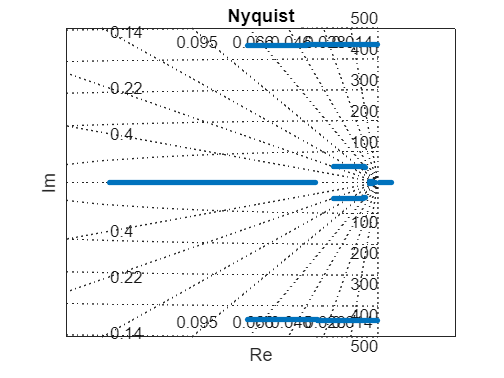

fig = figure();
axe = axes(fig);

scatter(axe,real(poles),imag(poles), ...
    10, ...
    "filled" ...
    );

xticks(axe,[]);
yticks(axe,[]);
title(axe,"Nyquist");
xlabel(axe,"Re");
ylabel(axe,"Im");
box(axe,"on");
sgrid(axe);

## BikeSim results

vx = 110;
n2s = @num2str;
results_path = "G:\My Drive\BikeSimResults\BigSports\OpenLoop";
speed_path = "\Vx" + n2s(vx) + "Kph\";
file_name = "bikesim_results_" + n2s(vx) + "kph.csv";
results = readtable(results_path + speed_path + file_name);

time = results.Time;
camber = results.Roll;
steer = results.Steer;
wz = results.AV_Y;
vy = results.Vy./3.6;
wx = results.AVx;
ws = -results.M_StrSys./0.2212;
Yr = results.Fy_2;
Yf = results.Fy_1;

s = (180/pi).*[1,1,1,0,1,1,0,0] + [0,0,0,1,0,0,1,1];
x_mes = [camber,steer,wz,vy,wx,ws,Yr,Yf];

Mz = results.M_Str_In;

## Model results

sys = plant(params(vx));
x_sys = s.*lsim(sys,Mz,time);

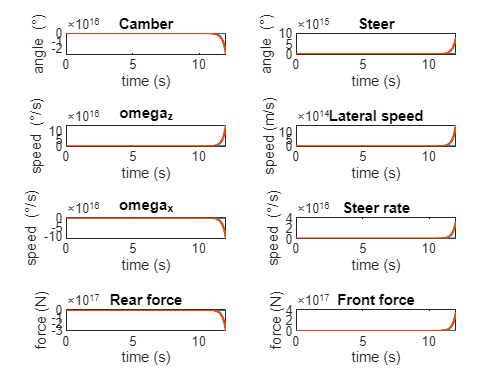

fig = figure();
tl = tiledlayout(4,2,"Parent",fig);

titles = [
    "Camber";
    "Steer";
    "omega_z";
    "Lateral speed";
    "omega_x";
    "Steer rate";
    "Rear force";
    "Front force"
    ];

units = [
    "angle (\circ)";
    "angle (\circ)";
    "speed (\circ/s)";
    "speed (m/s)";
    "speed (\circ/s)";
    "speed (\circ/s)";
    "force (N)";
    "force (N)"
    ];

for k = 1:8
    axe = nexttile(k);
    hold(axe,"on");
    plot(axe,time,x_mes(:,k),"LineWidth",1.5);
    plot(axe,time,x_sys(:,k),"LineWidth",1.5);
    hold(axe,"off");
    xlim(axe,[0,time(end)]);
    box(axe,"on");
    title(axe,titles(k));
    xlabel(axe,"time (s)");
    ylabel(axe,units(k));
end